# Link budget simulator explanation

This simulation considers the distance from the Spacecraft (S/C) to the Ground Station (G/S) and also the gain of the antenna radiation pattern that depends on the attitude of the satellite.

## 1. Simulation block areas

To run the simulation, first we clear the workspace

clear all   %#ok<CLALL> %clears all the workspace constants, structures and variables
close all   %closes all plot or simulation windows
clc         %cleans the command window

The simulation is composed of the following blocks:

### a. Orbit and attitude

This block only calculates the position of the attitude of the satellite, it requires initial orbit and attitude definition parameters:

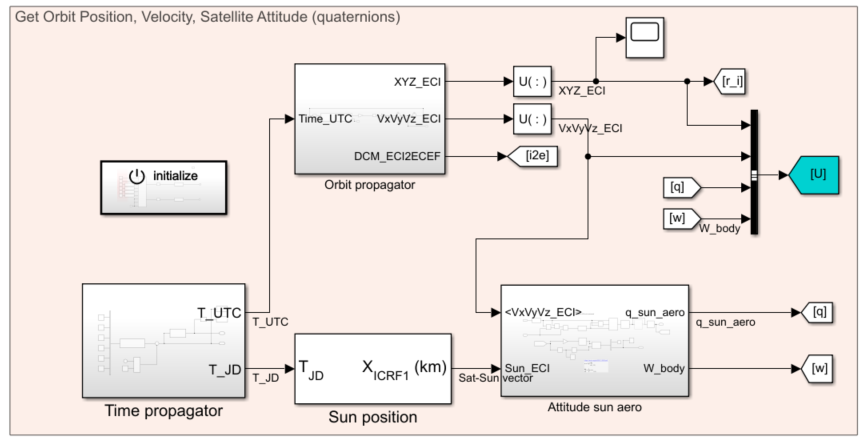

%Orbit simulation
%The object is assumed submitted only to gravity and it's mass is m in kg
m = 11; %mass (kg)

%Initialisation of Keplerian parameters
orbit.a = 6678; %semimajor axis (km)
orbit.e = 0.001; %eccentricity
orbit.i = 51.6; %inclination (degrees)
orbit.O = 120; %Right ascension of the right ascending node (degrees) %max 197, min 300.5 %181
orbit.o = 90; %Argument of the perigee (degrees)                      %max 90, min 0      %90
orbit.nu = 0; %True anomaly (degrees)

%Initialisation of date
date.year = 2020;
date.month = 1;
date.day = 1;
date.hours = 4;
date.minutes = 0;
date.seconds = 0;

%Simulation time parameters
N_orbits = 3;
%Torbit=90*60;       %1 orbit approx. 90 minutes
Torbit=2*pi*sqrt((orbit.a)^3/(3.986004418E5));
%tsimulation=60*45;   %in [s] 1 orbit
tsimulation=N_orbits*Torbit;
%tsimulation=10000;
%tsimulation=2700;
delta_t = 0.5; %simulation time step (seconds)

### b. Range and visibility of the S/C to the G/S

The range is easy to calculate:

The ground station is defined in Latitude, Longitude and altitude, from that, it can be easily converted to the ECEF reference frame, and from there to the ECI frame, the position of the spacecrat and the groun station is a vectorial substraction. The norm of this vector is the range.

The visibility can be done in different ways, but in this implementation, two criteria for visibility are considered:

- The distance from the G/S to the S/C does not exceed a maximum limit, this is not a hard criteria, it depends on different factors and will also be taken into account in the Link Budget calculation, therefore, a safe value for maximum distance is 5000km or more.

- The minimum elevation of the antenna from the GS pointing to the satellite, this is typically 5 to 10 degrees, although it depends on the location of the ground station, for example, trees might represent an obstacle in the line of sight, and the minimum elevation possible should go above trees in some directions. A more advanced simulation, should consider that for different values of azimuth there are different values of minimum elevation, but in this example, the minimum elevation is set for any value of Azimuth.

The code is like the following:

%% Ground Station parameters
lat=43.6;    %latitude GS in degrees
long=1.44;   %longitude GS in degrees
h=189;       %altitude GS in meters
%R_earth = 6.3712e+6; %Earth radius
%alt_orbit=orbit.a*1000-R_earth;
%d_0=(sqrt((R_earth+alt_orbit)^2-R_earth^2))/1000;
%slant_range=sqrt(R_earth^2+(R_earth+alt_orbit)^2 - (2*R_earth*(R_earth+alt_orbit)*cos(acos(R_earth/(R_earth+alt_orbit))*cos(Coelevation)-Coelevation)));
d_max=5000;     %maximum distance for communication [km]
El_min=10;      %minimum elevation from the GS to the Sat [degrees].
El_min=0;      %minimum elevation from the GS to the Sat [degrees].

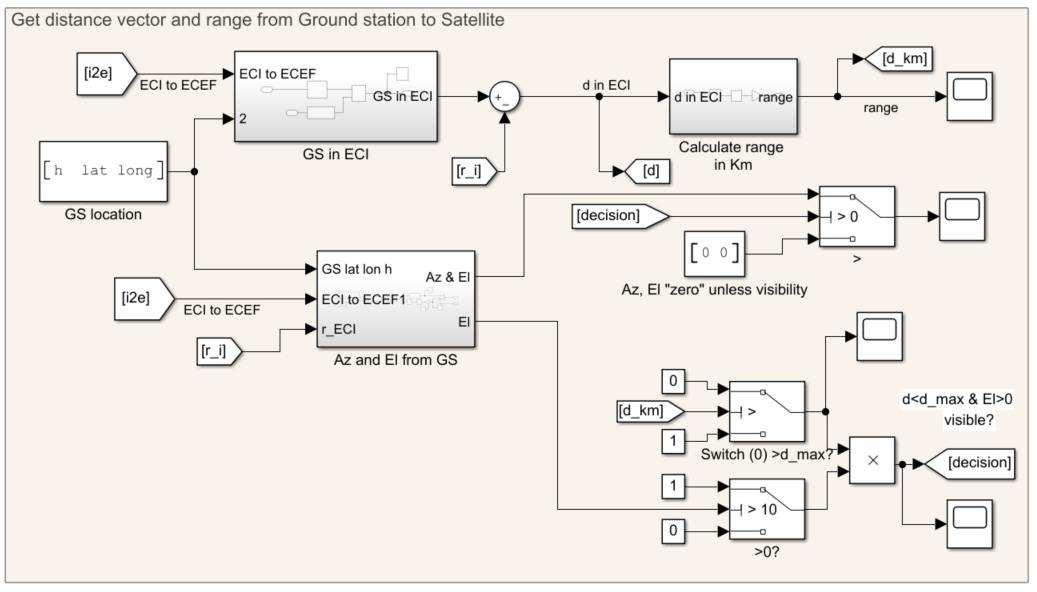

In the blocks implementation, there is a block that calculates the azimuth and elevation from the ground station. Using the information and the distance from the ground station, the decision of visibility is taken. If the satellite is visible the link budget will be calculated, if the satellite is not visible, no link budget is calculated.

Note that since it is expected that two different ground stations will be used for each communication band (UHF & S-band), two separate blocks should be implemented, including two different distances between the ground station and the satellite and two different visibility conditions.

### c. The link budget in UHF and S-band

First of all it is necessary to load the gain of the antennas.

Because there are two antennas, in S-band and UHF, two different matrices are loaded. These matrices are stored in a .mat file named "antennagain3.mat". These matrices represent the gain of the antennas in Azimuth and Co-elevation, represented as the gain in steps of 5 degrees.

load('antennagain3.mat')    %this .mat file has the matrix of gains used in the antennas.
global Guhf Gs_band Azimuth Coelevation

stp=5; %Step for interpolation (has to be the same as the one in the matrices Guhf, etc)
Azimuth=[0:stp:360];
Coelevation=[0:stp:180];

This gain is used together with the distance from the satellite to the ground station to quantify the link budget.

orbitcom_R20b_v6
%data=sim('orbitcom_R20b_v6');

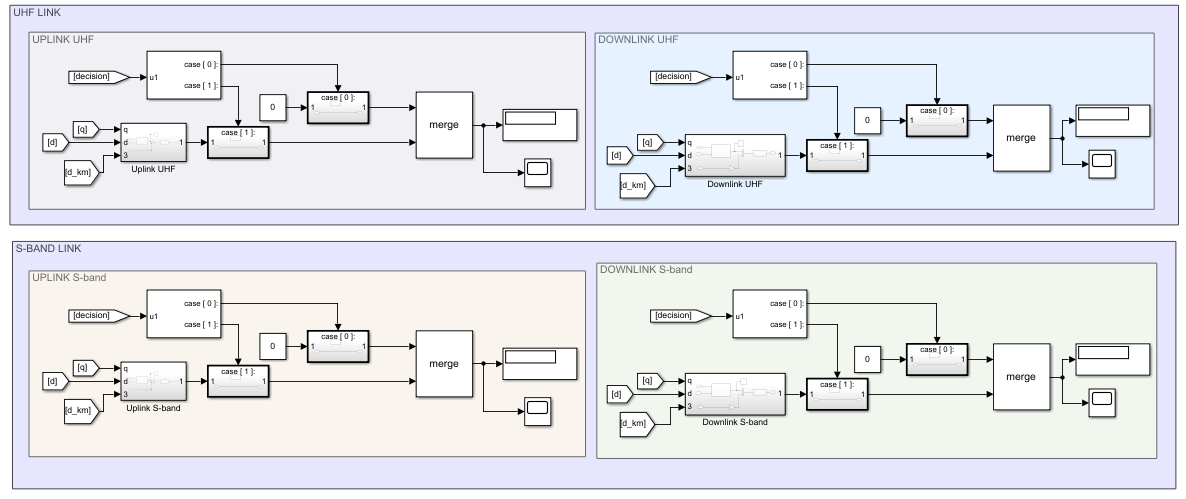

The implementation of the link margin is as follow:

- When the satellite is not in visibility (decision = 0), the link margin will always display "0".

- When the satellite is in visibility, (decision = 1), the link margin will display the result of the link margin calculation.

A typical result of the link margin is like the following:

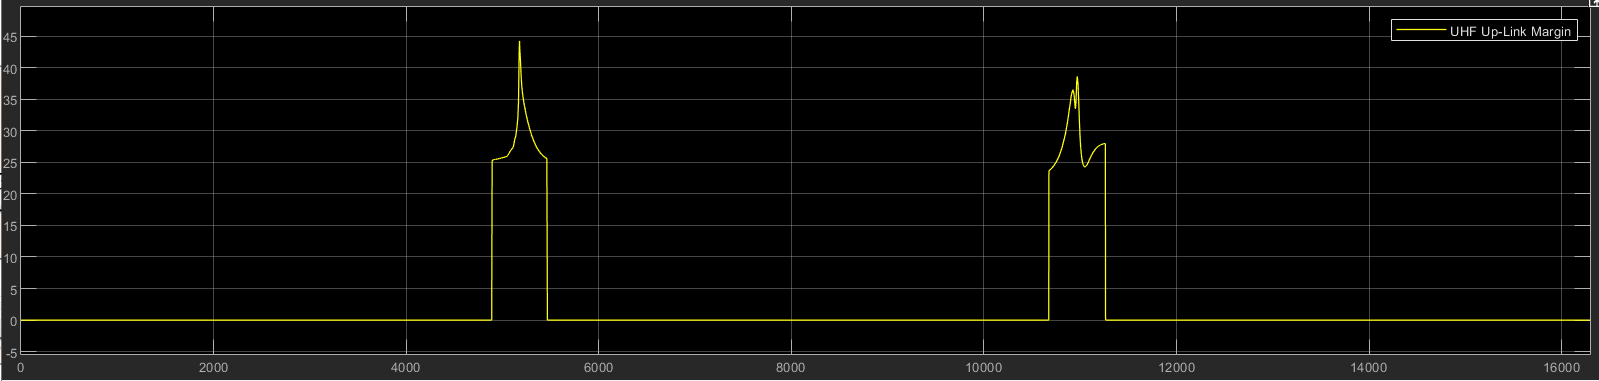

During visibility windows, the link margin is positive and the satellite communications is possible. If the link margin is negative, the satellite communications is not feasible.